**Top Line Summary**

*Parametric equations enable us to represent a coordinate system s and t as two separate functions of y which allows us to plot a single curve of the functions s and t. *

*We produce a parametric log-log plot of *$s=f\left(y\right)$* and *$t=g\left(y\right)$* with *$f\left(y\right)$* and  *$g\left(y\right)$* defined in Q1. (b), using *$n=200$* for y*$\in \left\lbrack 1,2\right\rbrack$

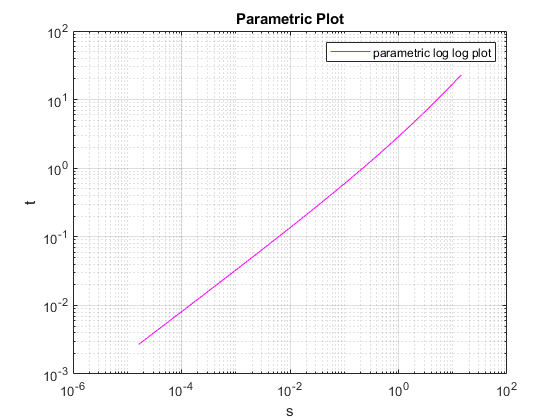

y0 = 1;
yN = 2;%with dotted magenta line 
n = 200;%with 200 = n
y = linspace(y0, yN, n);%equally spaced points

f_y = y.*(2*y.^2-5).*((y.^2)-1).^(0.5)+3*log(y+(y.^2-1).^0.5);
g_y = y.*(2*y.^2-1).*((y.^2)-1).^(0.5)-log(y+(y.^2-1).^0.5);

%setup parameters t and s as described in the instructions
s = f_y;
t = g_y;

t_s = loglog(s,t,'-m');
legend('parametric log log plot','Location', 'northeast')
grid on
xlabel('s')
ylabel('t')
title('Parametric Plot')